Interface de texto para PVI

Autor:

  - Arménio Correia  .: armenioc@isec.pt

  - Ana Rita Conceição Pessoa - 2023112690 

  - João Francisco de Matos Claro - 2023112690 

Data : 13/03/2024

clear

colors = [[0, 0.4470, 0.7410]; ...
    [0.8500, 0.3250, 0.0980]; ...
    [0.9290, 0.6940, 0.1250]; ...
    [0.4940, 0.1840, 0.5560]; ...
    [0.4660, 0.6740, 0.1880]; ...
    [0.3010, 0.7450, 0.9330]; ...
    [0.6350, 0.0780, 0.1840]];

strF="y+exp(3*t)";
f=str2func(vectorize(strcat('@(t,y)', " ", strF)));
a = 0;
b = 1.5;
if ~(isscalar(b) && b > a)
    disp("Introduza um b > a");
end
n = 3;
if ~(isscalar(n) && n==floor(n) && n > 0)
    disp("Introduza um valor de n correto");
end
y0 = 2;

%Variables for ploting
h = (b-a)/n;
t = a:h:b;

yValue(:,1) = t.';
methods(1) = "t";

% Alinha automaticamente os graficos consoante o numero
% de metodos na figura
tiledlayout('flow');

if(true)
    [~, y]=NEuler(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Euler", y, t, colors(length(methods), :));
    methods(end+1) = "Euler";
end
if(true)
    [~, y]=NEulerMelhorado(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Euler Melhorado", y, t, colors(length(methods), :));
    methods(end+1) = "Euler M";
end
if(true)
    [~, y]=RK2(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("RK2", y, t, colors(length(methods), :));
    methods(end+1) = "RK2";
end
if(true)
    [~, y]=RK4(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("RK4", y, t, colors(length(methods), :));
    methods(end+1) = "RK4";
end
if(true)
    [~, y]=AdamBashforth(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Adams-Bashforth", y, t, colors(length(methods), :));
    methods(end+1) = "Adams-Bashforth";
end
if(true)
    [~, y]=sExata(f,a,b,n,y0);
    
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Exata", y, t, colors(length(methods), :));
    methods(end+1) = "Exata";
end 
if(false)
    [t, y]=ode45(f, [a b], y0);

    %nao pode ser usada na funcao mostraGrafico
    %porque usa um t diferente das outras funcoes
    fprintf("\nAproximações obtidas de ode45:\n");
    disp(table(y));
    mostraGrafico("ode45", y, t, colors(length(methods), :));
    fprintf('\nPontos de aproximação da ode45\n');
    disp(table(t));
end

data = array2table(yValue, 'VariableNames', methods);
disp(data);

     t     Euler     Euler M     RK2       RK4      Adams-Bashforth    Exata 
    ___    ______    _______    ______    ______    _______________    ______

      0         2         2          2         2             2              2
    0.5       3.5      4.25     4.7454    4.4043             2         4.7139
      1    7.4908    10.799     14.413    12.348        10.973          14.12
    1.5    21.279    33.962     53.458     43.36         56.81         51.731



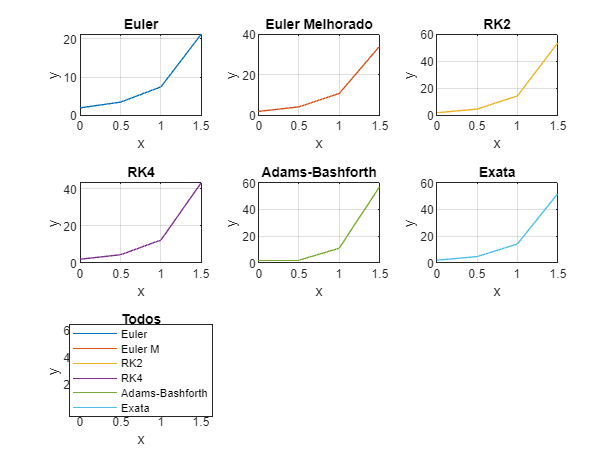


mostraTodos(methods, yValue, colors); 

clf reset;

function mostraGrafico(metodo, y, t, cor)   
    nexttile
    plot (t, y, 'DisplayName', metodo, 'Color', cor);
    title(metodo);
    xlabel('x');
    ylabel('y');
    grid on
end

function mostraTodos(metodo, y, colors) 
% Desenha todos num unico grafico
    nexttile
    title("Todos");
    % y(1) tem os valores de T
    for i = 2:length(y)
        hold on
        plot (y(:,1).', y(:, i).', 'DisplayName', metodo(i), 'Color', colors((i-1),:));
        % legend('location', 'best');
        xlabel('x');
        ylabel('y');
        hold off
        grid on
    end
end
